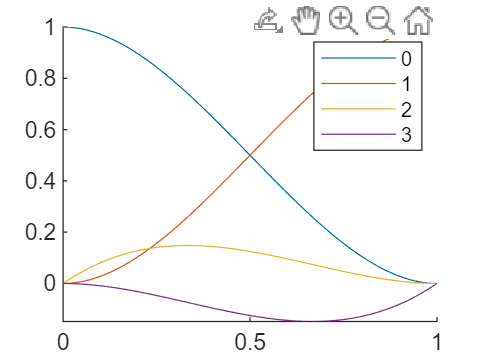

clear; 

syms h u t u0 u1 f0 f1

b0 = getPoly(t, 1, [1,0,0,0]');
b1 = getPoly(t, 1, [0,1,0,0]');
b2 = getPoly(t, 1, [0,0,1,0]');
b3 = getPoly(t, 1, [0,0,0,1]');
figure(1); clf;hold on;
fplot(b0,[0,1])
fplot(b1,[0,1])
fplot(b2,[0,1])
fplot(b3,[0,1])
hold off;
legend('0','1','2','3');

## integration

syms alpha alpha2 v0 v1 v2
bases(t) = [1,t,t^2];
bases2(t) = [1,t,t^2,t^3]; % _2 is for 3rd degree poly integration
weights = int(bases / ([bases(0);bases(alpha); bases(1)]),t,0,1)

$$weights = \left(\begin{array}{ccc} \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

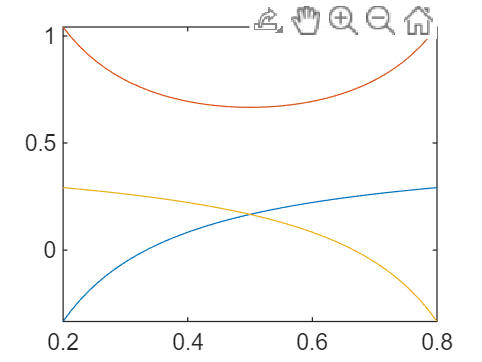

fplot(weights, [0.2,0.8])

weights2 = int(bases2 / ([bases2(0);bases2(alpha);bases2(alpha2); bases2(1)]),t,0,1)

$$weights2 = \begin{array}{l} \left(\begin{array}{cccc} \frac{\frac{\alpha }{2}-\frac{1}{6}}{\alpha }-\frac{\sigma_{1}}{\alpha \,\alpha_{2}} & \frac{2\,\alpha_{2}-1}{12\,\alpha \,\left(\alpha -\alpha_{2}\right)\,\left(\alpha -1\right)} & -\frac{2\,\alpha -1}{12\,\alpha_{2}\,\left(\alpha -\alpha_{2}\right)\,\left(\alpha_{2}-1\right)} & \frac{\frac{\alpha }{2}-\frac{1}{3}}{\alpha -1}+\frac{\sigma_{1}}{\left(\alpha -1\right)\,\left(\alpha_{2}-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\alpha }{6}-\frac{1}{12} \end{array}$$

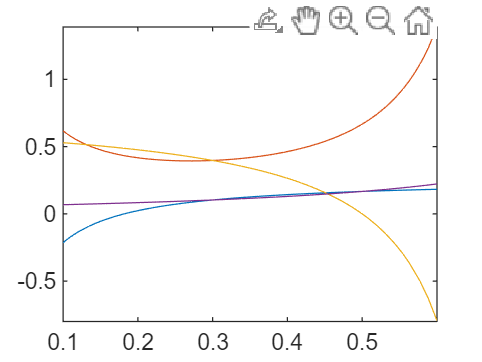

fplot(subs(weights2,alpha2,0.7), [0.1,0.6])

## input

u_mid = [b0(alpha),b1(alpha),b2(alpha)*h,b3(alpha)*h] * transpose([u0,u1,f0,f1])

$$u\_mid = u_{0}\,\left(2\,\alpha^{3}-3\,\alpha^{2}+1\right)+u_{1}\,\left(3\,\alpha^{2}-2\,\alpha^{3}\right)-f_{1}\,h\,\left(\alpha^{2}-\alpha^{3}\right)+f_{0}\,h\,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)$$

u_mid2 = [b0(alpha2),b1(alpha2),b2(alpha2)*h,b3(alpha2)*h] * transpose([u0,u1,f0,f1])

$$u\_mid2 = u_{0}\,\left(2\,{\alpha_{2}}^{3}-3\,{\alpha_{2}}^{2}+1\right)+u_{1}\,\left(3\,{\alpha_{2}}^{2}-2\,{\alpha_{2}}^{3}\right)-f_{1}\,h\,\left({\alpha_{2}}^{2}-{\alpha_{2}}^{3}\right)+f_{0}\,h\,\left({\alpha_{2}}^{3}-2\,{\alpha_{2}}^{2}+\alpha_{2}\right)$$

syms f_mid f_mid2;
incre = weights * [f0; f_mid; f1] * h;
incre2 = weights2 * [f0; f_mid; f_mid2; f1] * h;

% for use:
coefsN = [b0(alpha),b1(alpha),b2(alpha),b3(alpha)]

$$coefsN = \left(\begin{array}{cccc} 2\,\alpha^{3}-3\,\alpha^{2}+1 & 3\,\alpha^{2}-2\,\alpha^{3} & \alpha^{3}-2\,\alpha^{2}+\alpha & \alpha^{3}-\alpha^{2} \end{array}\right)$$

v = simplify(subs(coefsN,(3-sqrt(sym(3)))/6))

$$v = \left(\begin{array}{cccc} \frac{2\,\sqrt{3}}{9}+\frac{1}{2} & \frac{1}{2}-\frac{2\,\sqrt{3}}{9} & \frac{\sqrt{3}}{36}+\frac{1}{12} & \frac{\sqrt{3}}{36}-\frac{1}{12} \end{array}\right)$$

v(1)

$$ans = \frac{2\,\sqrt{3}}{9}+\frac{1}{2}$$

1- v(1)

$$ans = \frac{1}{2}-\frac{2\,\sqrt{3}}{9}$$

v(1)/2  - (2 + sqrt(sym(3)))/12

$$ans = \frac{\sqrt{3}}{36}+\frac{1}{12}$$

## linear stability

syms lambda kappa
u_mid_lam = subs(u_mid, [f0,f1],[u0,u1] * lambda);
u_mid2_lam = subs(u_mid2, [f0,f1],[u0,u1] * lambda);

incre_lam = collect(subs(expand(incre), [f0,f_mid,f1], [u0*lambda,u_mid_lam*lambda,u1*lambda]), [u0,u1])

$$incre\_lam = \begin{array}{l} \left(\frac{h\,\lambda }{2}-\frac{h\,\lambda }{6\,\alpha }+\frac{h\,\lambda \,\left(-3\,\alpha^{2}+2\,\alpha^{3}+h\,\lambda \,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)+1\right)}{\sigma_{1}}\right)\,u_{0}+\left(\frac{h\,\lambda }{2}+\frac{h\,\lambda }{6\,\left(\alpha -1\right)}-\frac{h\,\lambda \,\left(2\,\alpha^{3}-3\,\alpha^{2}+h\,\lambda \,\left(\alpha^{2}-\alpha^{3}\right)\right)}{\sigma_{1}}\right)\,u_{1}\\ \mathrm{where}\\ \sigma_{1}=\left(\alpha -\alpha^{2}\right)\,6 \end{array}$$

K = subs(simplify(solve(incre_lam + (u0 - u1), u1 )/u0), h*lambda, kappa)

$$K = -\frac{4\,\kappa -2\,\alpha \,\kappa -\alpha \,\kappa^{2}+\kappa^{2}+6}{2\,\kappa +2\,\alpha \,\kappa -\alpha \,\kappa^{2}-6}$$


incre2_lam = collect(subs(expand(incre2), [f0,f_mid, f_mid2,f1], [u0,u_mid_lam, u_mid2_lam,u1]*lambda), [u0,u1])

$$incre2\_lam = \begin{array}{l} \left(\frac{h\,\lambda }{2}-\frac{h\,\lambda }{6\,\alpha }-\frac{h\,\lambda }{6\,\alpha_{2}}+\frac{h\,\lambda }{12\,\alpha \,\alpha_{2}}-\frac{h\,\lambda \,\sigma_{2}}{\sigma_{6}\,12}-\frac{h\,\lambda \,\sigma_{1}}{\sigma_{5}\,12}+\frac{\alpha_{2}\,h\,\lambda \,\sigma_{2}}{\sigma_{6}\,6}+\frac{\alpha \,h\,\lambda \,\sigma_{1}}{\sigma_{5}\,6}\right)\,u_{0}+\left(-\frac{h\,\lambda }{3\,\left(\alpha -1\right)}+\frac{h\,\lambda }{12\,\sigma_{7}}-\frac{\alpha \,h\,\lambda }{6\,\sigma_{7}}+\frac{h\,\lambda \,\sigma_{3}}{\sigma_{6}\,12}+\frac{h\,\lambda \,\sigma_{4}}{\sigma_{5}\,12}+\frac{\alpha \,h\,\lambda }{2\,\left(\alpha -1\right)}-\frac{\alpha_{2}\,h\,\lambda \,\sigma_{3}}{\sigma_{6}\,6}-\frac{\alpha \,h\,\lambda \,\sigma_{4}}{\sigma_{5}\,6}\right)\,u_{1}\\ \mathrm{where}\\ \sigma_{1}=-3\,{\alpha_{2}}^{2}+2\,{\alpha_{2}}^{3}+h\,\lambda \,\left({\alpha_{2}}^{3}-2\,{\alpha_{2}}^{2}+\alpha_{2}\right)+1\\ \sigma_{2}=-3\,\alpha^{2}+2\,\alpha^{3}+h\,\lambda \,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)+1\\ \sigma_{3}=2\,\alpha^{3}-3\,\alpha^{2}+h\,\lambda \,\left(\alpha^{2}-\alpha^{3}\right)\\ \sigma_{4}=2\,{\alpha_{2}}^{3}-3\,{\alpha_{2}}^{2}+h\,\lambda \,\left({\alpha_{2}}^{2}-{\alpha_{2}}^{3}\right)\\ \sigma_{5}=\alpha \,\alpha_{2}-\alpha \,{\alpha_{2}}^{2}-{\alpha_{2}}^{2}+{\alpha_{2}}^{3}\\ \sigma_{6}=\alpha \,\alpha_{2}-\alpha^{2}\,\alpha_{2}-\alpha^{2}+\alpha^{3}\\ \sigma_{7}=\alpha +\alpha_{2}-\alpha \,\alpha_{2}-1 \end{array}$$

K2 = subs(simplify(solve(incre2_lam + (u0 - u1), u1 )/u0), h*lambda, kappa)

$$K2 = \frac{\kappa^{2}+6\,\kappa +12}{\kappa^{2}-6\,\kappa +12}$$

## stablility region

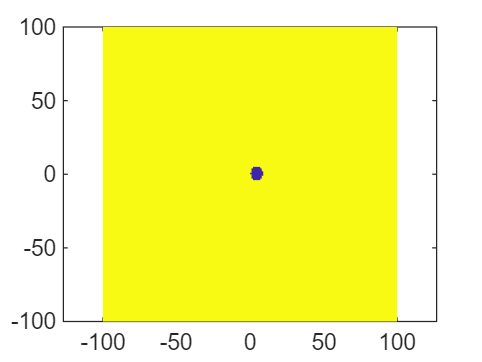

test_range = 100;
rSamp = linspace(-test_range,test_range,201);
iSamp = linspace(-test_range,test_range,201);
[rSampM,iSampM] = meshgrid(rSamp,iSamp);
zSampM = rSampM + 1i * iSampM;
Kf = matlabFunction(symfun(K, [kappa, alpha]));
Kf2 = matlabFunction(symfun(K2, [kappa, alpha, alpha2]));
alphatest = 0.86;
% alphatest = 2/3;
KM = abs(Kf(zSampM, alphatest));
KM2 = abs(Kf2(zSampM, alphatest, 1 - alphatest));

p = pcolor(rSampM,iSampM, double(KM < 1));
p.EdgeColor = 'none';
axis equal;

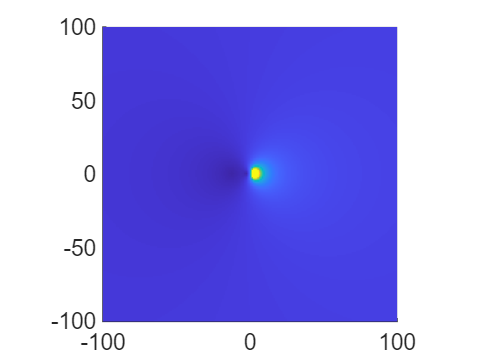


s = surf(rSampM,iSampM, double(min(KM,2)));
s.EdgeColor = 'none';
axis equal;
view(0,90)

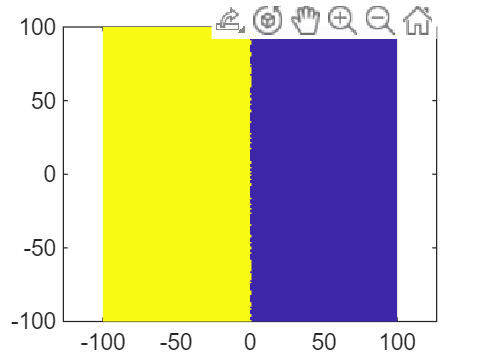


p = pcolor(rSampM,iSampM, double(KM2 < 1));
p.EdgeColor = 'none';
axis equal;

## jacobian

syms J J_m idt
c = sym("c",[4,1]);
w = sym("w",[3,1]);
JA = w(3) * J + w(2) * J_m * (J * c(4) * h + c(2)) - 1/h

$$JA = J\,w_{3}-\frac{1}{h}+J_{m}\,w_{2}\,\left(c_{2}+J\,c_{4}\,h\right)$$

JA1 = c(4)*w(2) * (J + c(2)/c(4)/h) * (J_m + w(3)/(c(4)*h * w(2))) * h

$$JA1 = c_{4}\,h\,w_{2}\,\left(J_{m}+\frac{w_{3}}{c_{4}\,h\,w_{2}}\right)\,\left(J+\frac{c_{2}}{c_{4}\,h}\right)$$

simplify(expand(JA1))

$$ans = \frac{\left(c_{2}+J\,c_{4}\,h\right)\,\left(w_{3}+J_{m}\,c_{4}\,h\,w_{2}\right)}{c_{4}\,h}$$

expand(JA - JA1)

$$ans = -\frac{1}{h}-\frac{c_{2}\,w_{3}}{c_{4}\,h}$$

simplify(subs(expand(JA - JA1), [c;w],[transpose(coefsN); transpose(weights)]) * h)

$$ans = -\frac{\alpha }{6\,{\left(\alpha -1\right)}^{2}}$$

subs((JA), [c;w],[transpose(subs(coefsN,alpha,1/2)); transpose(subs(weights,alpha,1/2))])

$$ans = \frac{J}{6}-\frac{2\,J_{m}\,\left(\frac{J\,h}{8}-\frac{1}{2}\right)}{3}-\frac{1}{h}$$

## jacobian 2

syms J1 Jm h CFL
Jorig = [w(3) * J1 - 1/h, w(2) * Jm; c(2)/h + c(4) * J1, -1/h]

$$Jorig = \left(\begin{array}{cc} J_{1}\,w_{3}-\frac{1}{h} & \mathrm{Jm}\,w_{2}\\ J_{1}\,c_{4}+\frac{c_{2}}{h} & -\frac{1}{h} \end{array}\right)$$

syms theta
rowT = [1 0; theta, 1];
swapRow = [0,1;1,0];
Jtheta = swapRow * rowT * Jorig * swapRow';
Jtheta = subs(Jtheta, [c;w], [transpose(coefsN); transpose(weights)]);
JthetaCh = subs(Jtheta, [J1,Jm], [-CFL/h, -CFL/h]) * h;
JthetaCh = simplify(expand(JthetaCh));
alphaSamp = 1/2;
% thetaSamp = -coefsN(4)/weights(3);
thetaSamp = 32/8;
JJ = simplify(subs(JthetaCh,[theta,alpha],...
    [thetaSamp,alphaSamp]));
JJ = simplify(subs(JJ,[theta,alpha],...
    [thetaSamp,alphaSamp]));
rhoJJ = -JJ(2,1) * JJ(1,2) / JJ(2,2) / JJ(1,1)

$$rhoJJ = -\frac{2\,\mathrm{CFL}\,\left(\frac{13\,\mathrm{CFL}}{24}+\frac{7}{2}\right)}{3\,\left(\frac{\mathrm{CFL}}{6}+1\right)\,\left(\frac{8\,\mathrm{CFL}}{3}+1\right)}$$

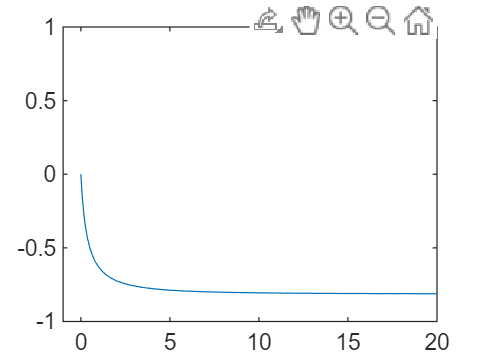


% thetaExtre = solve(diff(rhoJJ, CFL)==0, CFL)
% thetaExtreF = symfun(thetaExtre, theta);
% fplot(thetaExtreF)
% xlabel("\theta")

figure(2)
fplot(symfun((rhoJJ),CFL),[0,200])
xlim([-1,20])
ylim([-1,1])

## jacobian2 num find

alphaSamp = 0.51;
% thetaSamp = -coefsN(4)/weights(3);
thetaSamp = theta;
JJ = simplify(subs(JthetaCh,[theta,alpha],...
    [thetaSamp,alphaSamp]));
JJ = simplify(subs(JJ,[theta,alpha],...
    [thetaSamp,alphaSamp]));
rhoJJ = -JJ(2,1) * JJ(1,2) / JJ(2,2) / JJ(1,1)

$$rhoJJ = \frac{5000\,\mathrm{CFL}\,\left(\frac{127449\,\mathrm{CFL}}{1000000}-\theta -\frac{47\,\mathrm{CFL}\,\theta }{294}+\frac{257499}{500000}\right)}{7497\,\left(\frac{47\,\mathrm{CFL}}{294}+1\right)\,\left(\frac{5000\,\mathrm{CFL}\,\theta }{7497}+1\right)}$$

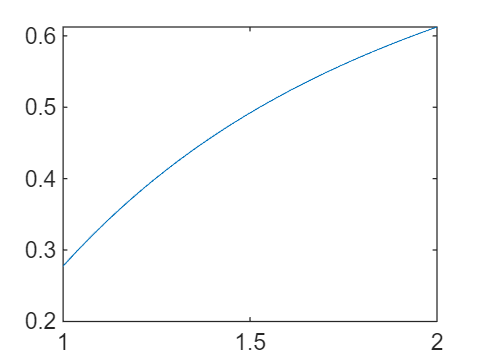

fRho = matlabFunction(symfun(abs(rhoJJ),[CFL, theta]));
CFLTests = [linspace(0,20,10001), logspace(21,1e4,10001)];
CFLTests(1) = 1e-3;
thetaTests = linspace(1,2,1001);
rhoTests = fRho(CFLTests, thetaTests');
rhoMTests = max(rhoTests,[],2);
plot(thetaTests,rhoMTests);

[minR, iminR] = min(rhoMTests,[],'all')

minR = 0.2775

iminR = 1

thetaM = thetaTests(iminR)

thetaM = 1

function po = getPoly(t, h, cond)
    bases(t) = [1,t,t^2,t^3];
    dB(t) = diff(bases,t);
    valBases = [bases(0); bases(h);...
        dB(0); dB(h)];
    coefs = valBases \ cond;
    po = bases * coefs;
end




